# Joint Lip Tongue 5-mechanism plus blood search

This is a sequential fitting approach.

The idea is that we fix a matrix with collagen1-smooth, FAD_webfluor, porphyrin and chlorophyll excitations. We choose those because the first two fit the lip data well.  This guarantees that we will be able to find a fit to the lip data at the end.

We use that fixed matrix in a search procedure that varies blood oxygen of collagen and searches for one more, additional fluorophore specified only as a skewed Gaussian with three parameters (mean, width, skew).  For this stage of the fit, we use the same blood density for all subjects.  At this stage, we are learning about the parameters of the skewed Gaussian.

We fix that skewed Gaussian and create a new fixed fluorophore matrix.  We use that fixed matrix to fit both the lip and the tongue data, allowing individual blood densities for each subject.

We do this spanning 500-700nm.

ieInit;
wave = 500:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;

## Load up the lip and tongue data.

subjects = {'Z','B','D','J'};

% These must be possible to fit, say by forcing some of the weights to be
% zero, because we saw them fit in s_oeBloodFluorophoreLipSrch700.mlx.
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
end

% These are the first data we use to find the skewed Gaussian.
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    tongueData = cat(2,tongueData,tmp);
end

% ieFigure; plot(wave,tongueData);


## Create the fixed fluorophores

The first two worked for the lip very well from 500-700nm (see s_oeBloodFluorophoreLipSrch700.mlx).  For the tongue, we add porphyrin and chlorophyl (see s_oeBloodFluorophoreTongueSrch700.mlx).

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor','PorphyrinBjurshammar','chlorophyllA-7'};
[fixedFluorophores,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## Call the joint search

We have fluorophores for the lip that we know can fit if we adjust the blood density for each subject.  Those are collagen1-smooth and FAD_webfluor.  Those are shown to work in s_oeBloodFluorophoreLipSrch700.mlx.

Here, we fix those two fluorophores and fit a first approximation to all the tongue data from all the subjects, getting an approximate extra skewed Gaussian and an overall blood density.  That fit includes porphyrin and chlorophyll.  We save that skewedGaussian as our one extra fluorophore.  We will allow the blood density to vary using those five terms (collagen1-smooth, FAD_webfluor, porphyrin, chlorophyll, skewedG).  

We don't need the last three for the lip. 

When wel use it to fit the tongue data, we apply it to each subject separately to find the blood density for that subject.

[global_params, weights, finalFluorophores] = oeSolveJoint(wave, tongueData, fixedFluorophores)

## Check the quality of the fit

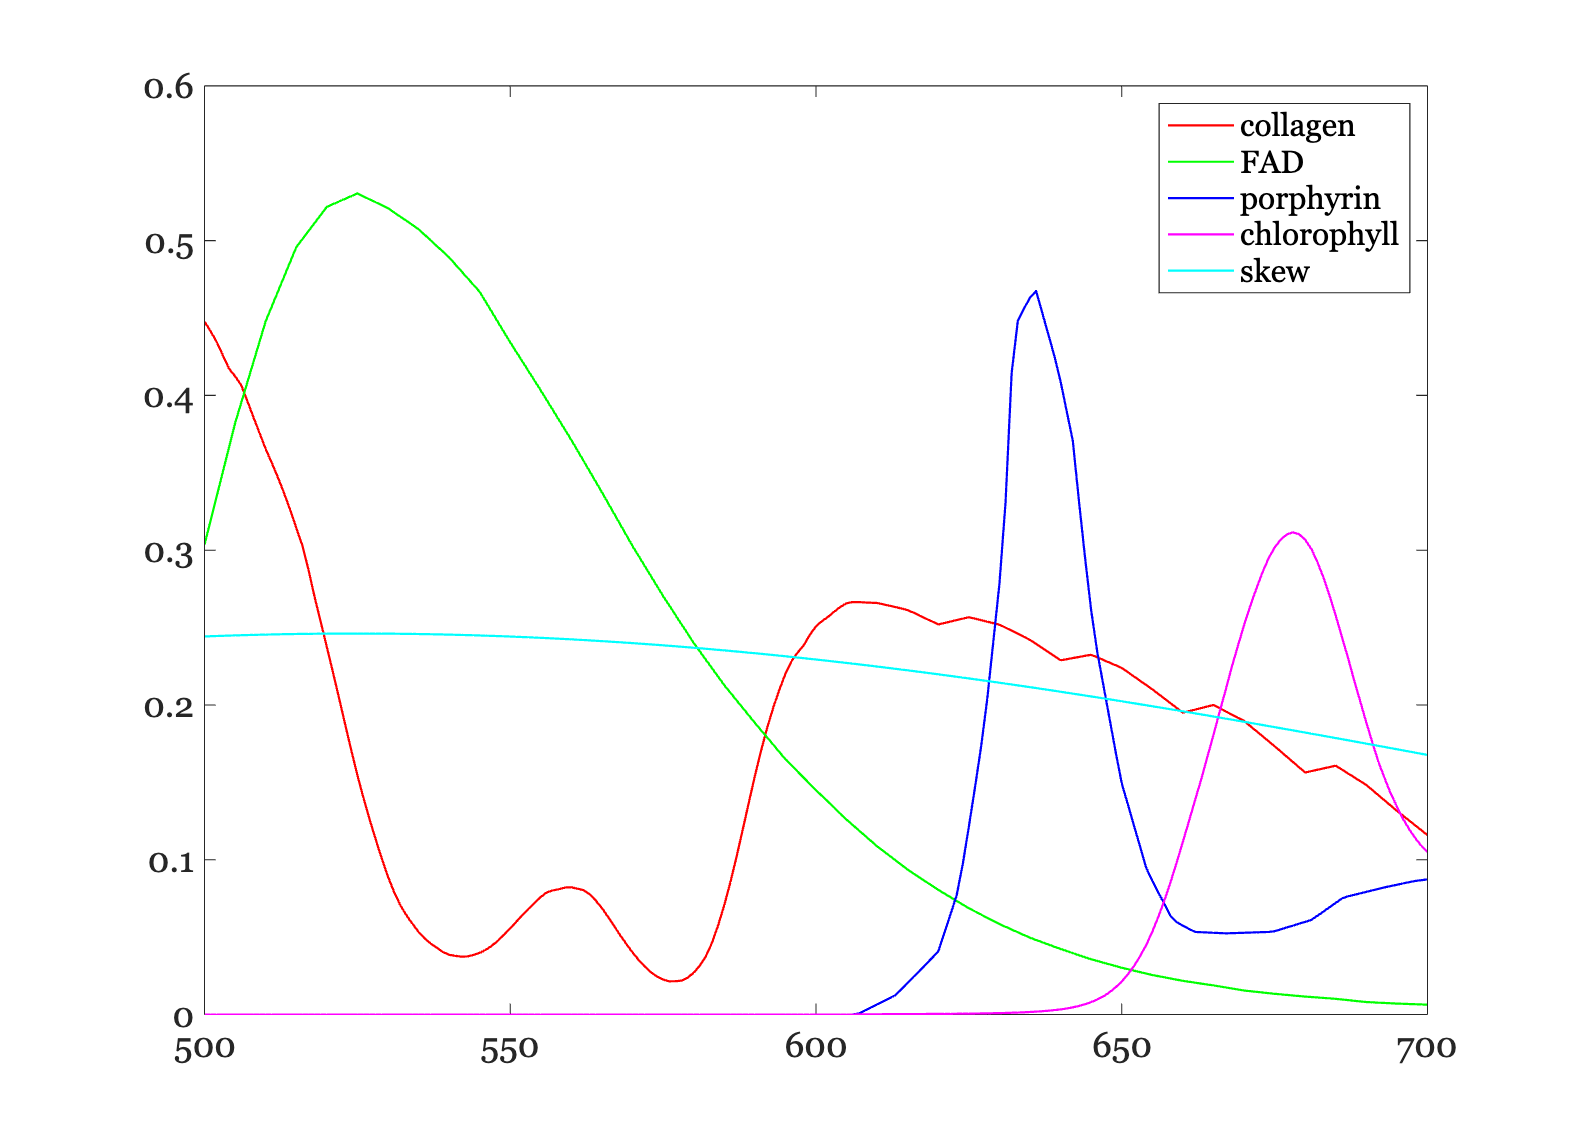

ieFigure;
% mean(weights,2)

plot(wave,finalFluorophores*diag(mean(weights,2)));
legend('collagen','FAD','porphyrin','chlorophyll','skew');

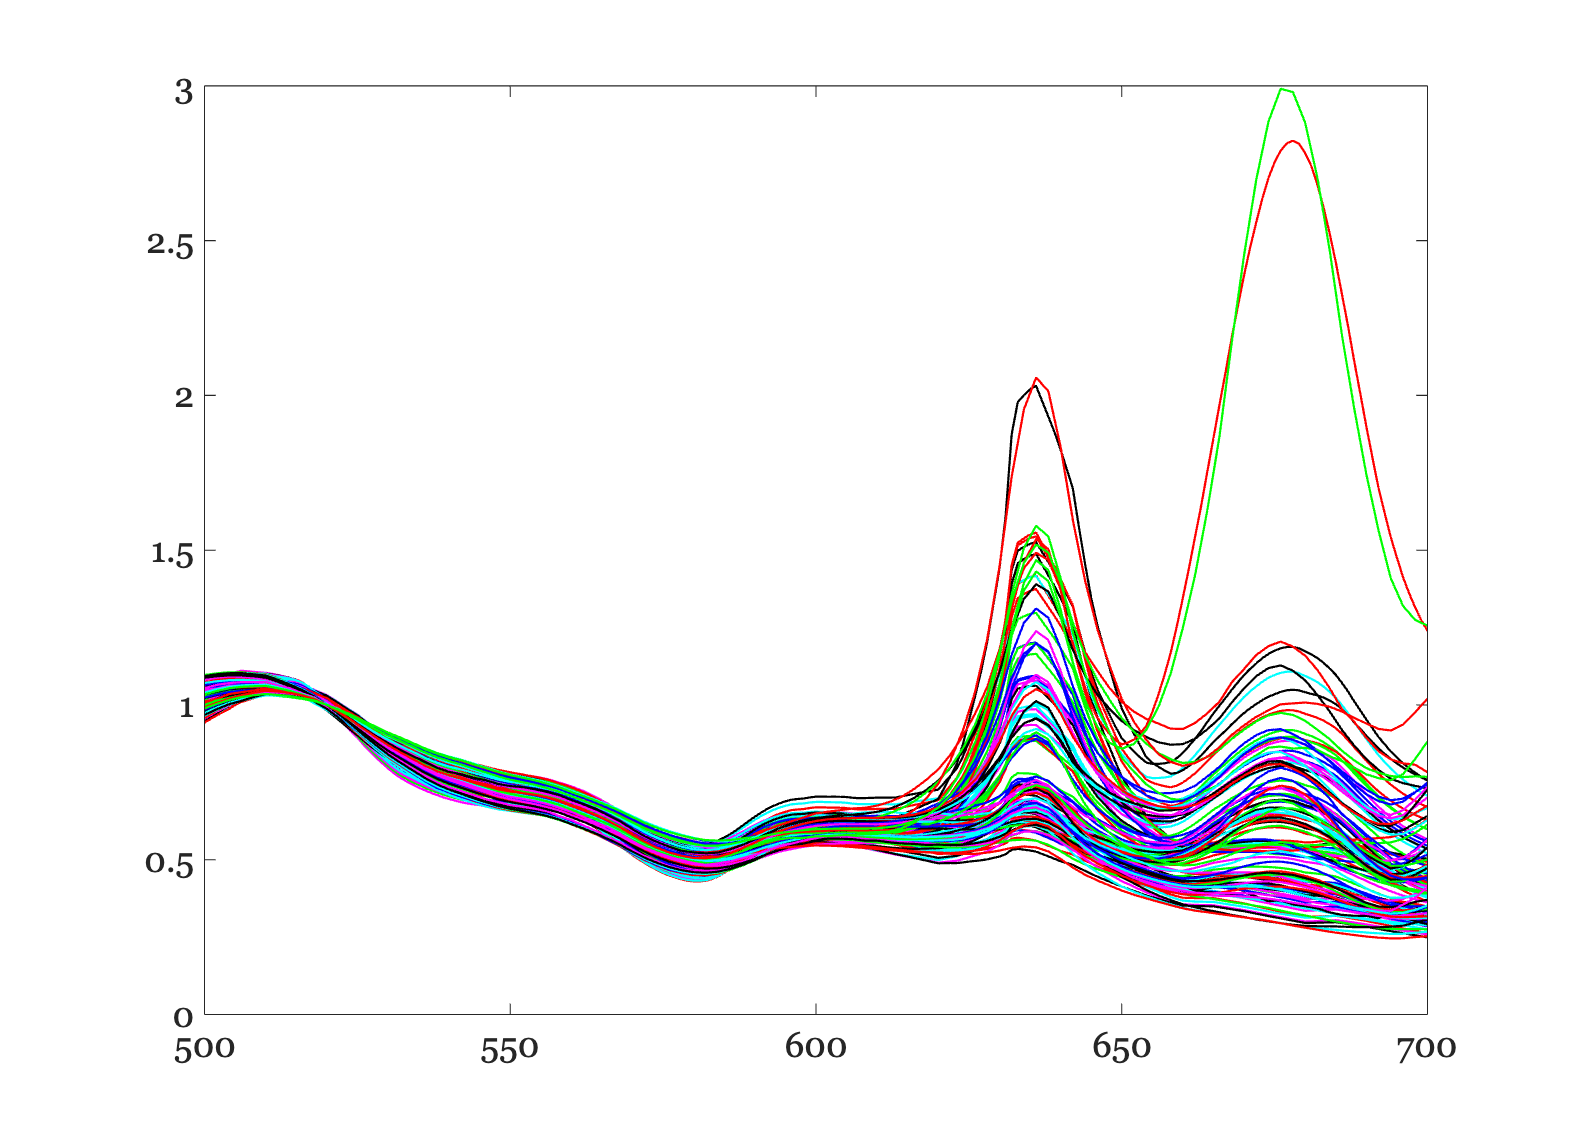

predicted = finalFluorophores*weights;
ieFigure; plot(wave,predicted); hold on;
plot(wave,tongueData);

%%
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
oxyblood.opticalDensity = 15;
oxyTransmittance = oxyblood.transmittance;
